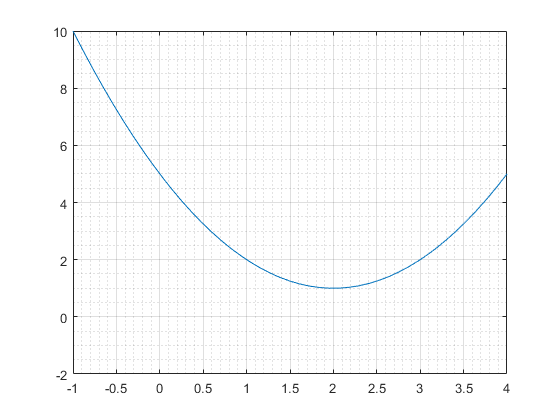

f = @(x) (x-2)^2+1;
fs = sym(f);

fplot(fs);
grid on;
grid minor;

axis([-1 4 -2 10]);


busquedaDorada(f,0,3)

ans = 2.0000

function x = busquedaDorada(f,x_l,x_u)
    max_iter = 52;
    tol = sqrt(eps);
    
    x = (x_l + x_u) / 2;
    g = ((1+sqrt(5))/2) - 1;
    d = g * (x_u - x_l);

    x1 = x_l + d;
    x2 = x_u - d;
    
    fx1 = f(x1);
    fx2 = f(x2);

    cond = true;
    i = 0;

    while cond
        d = g * d;
        
        if fx1 < fx2
            x_l = x2;
            x2 = x1;
            fx2 = fx1;
            x1 = x_l + d;
            fx1 = f(x1);
        else
            x_u = x1;
            x1 = x2;
            fx1 = fx2;
            x2 = x_u - d;
            fx2 = f(x2);
        end
        
        x = (x_l + x_u) / 2;
        i = i + 1;
        cond = i < max_iter && abs((x_u - x_l)/x) > tol;
    end
end